`Erfan Panahi   810198369`

## Digital Signal Processing (DSP)

# Computer Assignement 1

# ` Part 1:`

clear;
FsCT = 1000;
w = -pi:1/FsCT:pi;

`Problem 1.`

- 
$$x_1 \left\lbrack n\right\rbrack ={\left(0\ldotp 8\right)}^n \;\;\;,\;\;-10\le n\le 20$$


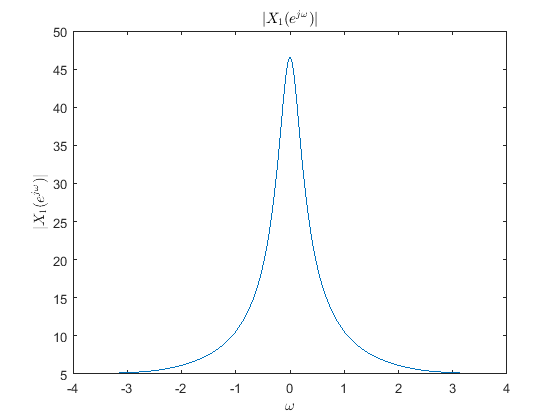

n_1 = -10:20;
x1 = 0.8.^n_1;
X1ejw = DTFT(x1,n_1,w);
plot(w,abs(X1ejw));
title('$|X_1(e^{j\omega})|$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|X_1(e^{j\omega})|$','Interpreter','latex');

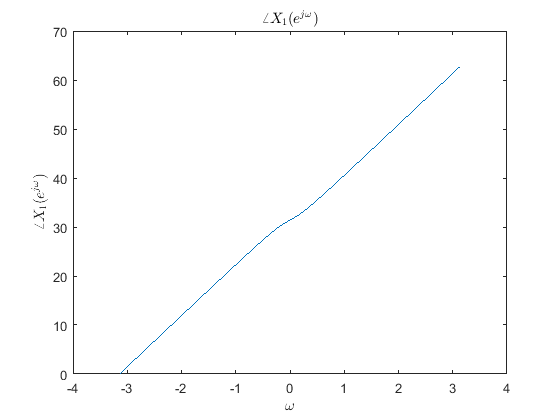

plot(w,phase(X1ejw));
title('$\angle{X_1(e^{j\omega})}$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{X_1(e^{j\omega})}$','Interpreter','latex');

- 
$$x_2 \left\lbrack n\right\rbrack =1\;\;,\;\;0\le n\le 40$$


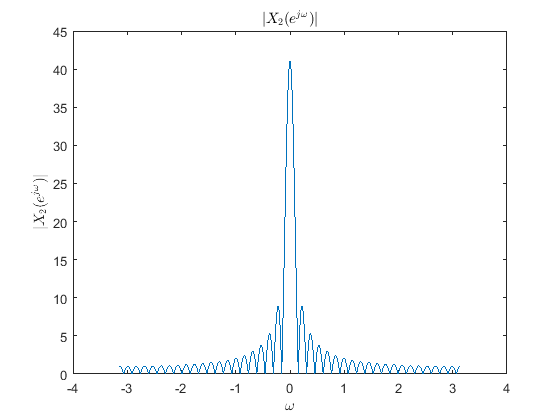

n_2 = 0:40;
x2 = 1.^n_2;
X2ejw = DTFT(x2,n_2,w);
plot(w,abs(X2ejw));
title('$|X_2(e^{j\omega})|$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|X_2(e^{j\omega})|$','Interpreter','latex');

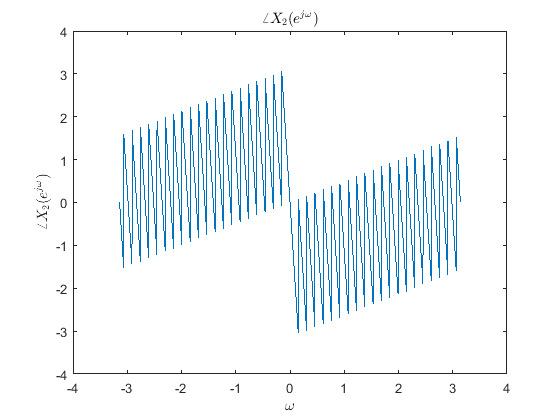

plot(w,phase(X2ejw));
title('$\angle{X_2(e^{j\omega})}$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{X_2(e^{j\omega})}$','Interpreter','latex');

`Problem 2.`

    
$$x_c \left(t\right)={\mathrm{sinc}}^2 \left(t\right)$$


t2 = -4:1/FsCT:4;
xc = sinc(t2).^2;
fsDT = 10;
n_d = (-4*fsDT):(4*fsDT);
xd = xc(1:FsCT/fsDT:length(xc));

- 
$$y\left\lbrack n\right\rbrack =x\left\lbrack \mathrm{Mn}\right\rbrack$$


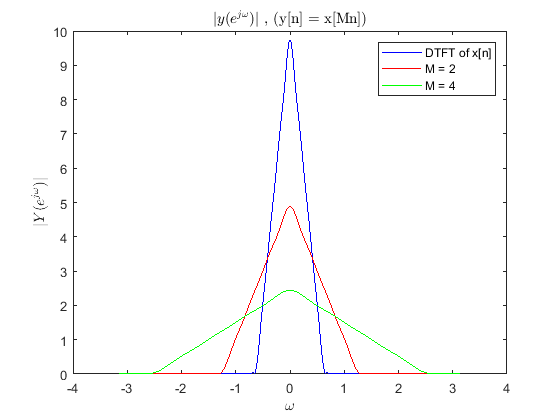

M = [2,4];
[xd_M2,n_M2] = Compressor(xd,n_d,M(1));
[xd_M4,n_M4] = Compressor(xd,n_d,M(2));
Xdejw = DTFT(xd,n_d,w);
Xdejw_M2 = DTFT(xd_M2,n_M2,w);
Xdejw_M4 = DTFT(xd_M4,n_M4,w);
plot(w,abs(Xdejw),'b',w,abs(Xdejw_M2),'r',w,abs(Xdejw_M4),'g');
title('$|y(e^{j\omega})|$ , (y[n] = x[Mn])','Interpreter','latex');
legend('DTFT of x[n]','M = 2','M = 4')
xlabel('$\omega$','Interpreter','latex');
ylabel('$|Y(e^{j\omega})|$','Interpreter','latex');

`Problem 3.`

- 
$$y\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{cc}
x\left\lbrack \frac{n}{L}\right\rbrack  & ,\;n=0,\pm L,\pm 2L,\ldotp \ldotp \ldotp \\
0 & ,o\ldotp w\ldotp 
\end{array}\right.$$


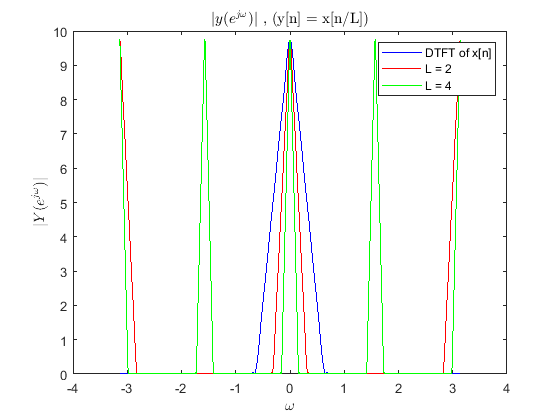

L = [2,4];
[xd_L2,n_L2] = Expander(xd,n_d,L(1));
[xd_L4,n_L4] = Expander(xd,n_d,L(2));
Xdejw_L2 = DTFT(xd_L2,n_L2,w);
Xdejw_L4 = DTFT(xd_L4,n_L4,w);
plot(w,abs(Xdejw),'b',w,abs(Xdejw_L2),'r',w,abs(Xdejw_L4),'g');
title('$|y(e^{j\omega})|$ , (y[n] = x[n/L])','Interpreter','latex');
legend('DTFT of x[n]','L = 2','L = 4')
xlabel('$\omega$','Interpreter','latex');
ylabel('$|Y(e^{j\omega})|$','Interpreter','latex');

`Problem 4.`

    
$$s\left(t\right)=\mathrm{cos}\left(2\pi f_c t\right)\;,{\;f}_c =10\mathrm{Hz}$$


t = 0:1/FsCT:1;
fc = 10;
s = cos(2*pi*fc*t);

- 
$$F_s =20\mathrm{Hz}$$


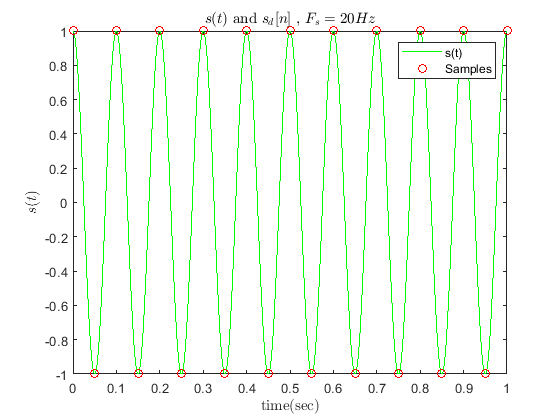

FS = 20;
sd = s(1:FsCT/FS:length(s));
n = 0:FS;
plot(t,s,'g',n/FS,sd,'ro');
title('$s(t)$ and $s_d[n]$ , $F_s=20Hz$','Interpreter','latex');
legend('s(t)','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$s(t)$','Interpreter','latex');

    
$$|S_d \left(e^{j\omega } \right)|$$


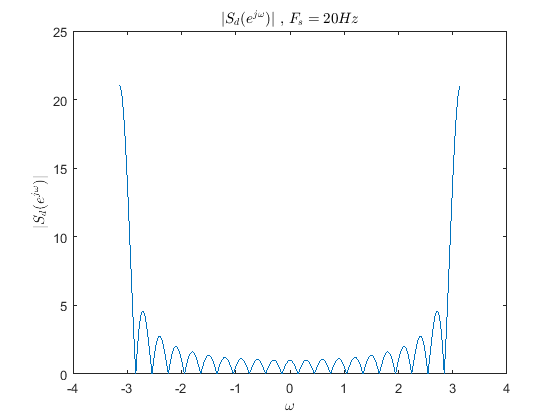

Sdejw = DTFT(sd,n,w);
plot(w,abs(Sdejw));
title('$|S_d(e^{j\omega})|$ , $F_s=20Hz$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S_d(e^{j\omega})|$','Interpreter','latex');

`Expander:`

`We use fc = 1000Hz for CT signals and fs = 20Hz:`

`So L must be 1000/20 = 50.`

L = FsCT/FS;
[se,ne] = Expander(sd,n,L);

`Interpolation (Mode 1):`

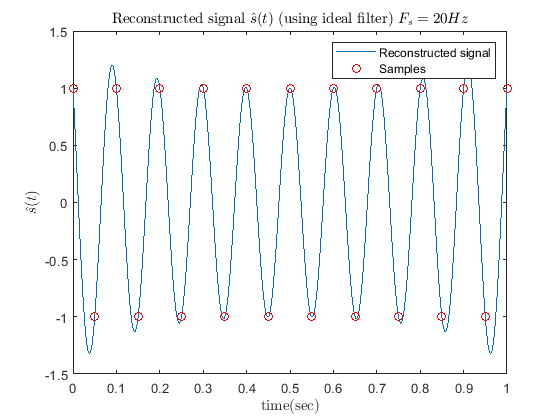

s_hat1_20 = Interpolate(se,ne,L,FS,1);
plot(t,s_hat1_20,n/FS,sd,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using ideal filter) $F_s=20Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Interpolation (Mode 2):`

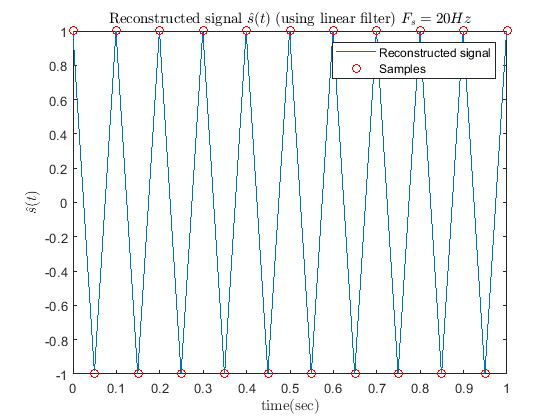

s_hat2_20 = Interpolate(se,ne,L,FS,2);
plot(t,s_hat2_20,n/FS,sd,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using linear filter) $F_s=20Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Interpolation (Mode 3):`

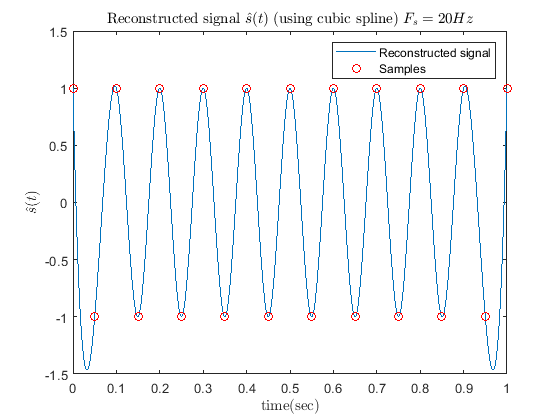

s_hat3_20 = Interpolate(se,ne,L,FS,3);
plot(t,s_hat3_20,n/FS,sd,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using cubic spline) $F_s=20Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Mean Squared Error: `

% Fs = 20Hz

- ` mode = 1 (ideal filter)`

Er20_ideal = immse(s_hat1_20,s)

Er20_ideal = 0.1125

        2. ` mode = 2 (linear filter)`

Er20_linear = immse(s_hat2_20,s)

Er20_linear = 0.0243

        3. ` mode = 3 (cubic spline)`

Er20_spline = immse(s_hat3_20,s)

Er20_spline = 0.1132

- 
$$F_s =200\textrm{Hz}$$


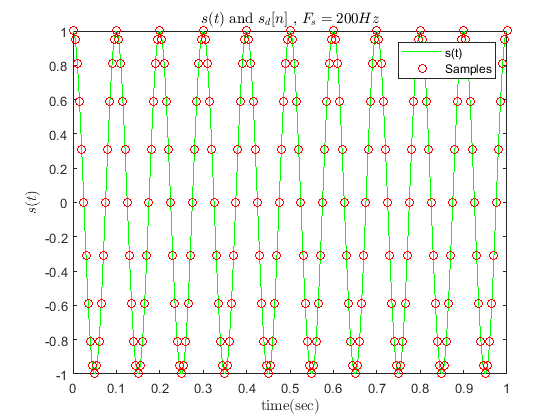

FS2 = 200;
sd2 = s(1:FsCT/FS2:length(s));
n2 = 0:FS2;
plot(t,s,'g',n2/FS2,sd2,'ro');
title('$s(t)$ and $s_d[n]$ , $F_s=200Hz$','Interpreter','latex');
legend('s(t)','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$s(t)$','Interpreter','latex');

    
$$|S_d \left(e^{j\omega } \right)|$$


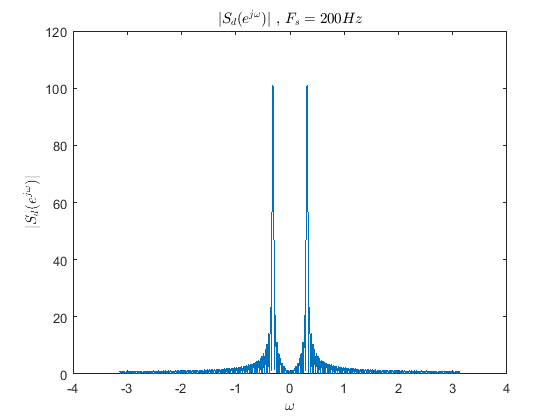

S2dejw = DTFT(sd2,n2,w);
plot(w,abs(S2dejw));
title('$|S_d(e^{j\omega})|$ , $F_s=200Hz$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S_d(e^{j\omega})|$','Interpreter','latex');

`Expander:`

`We use fs = 1000Hz for CT signals and fs = 20Hz:`

`So L must be 1000/20 = 50.`

L2 = FsCT/FS2;
[se2,ne2] = Expander(sd2,n2,L2);

`Interpolation (Mode 1):`

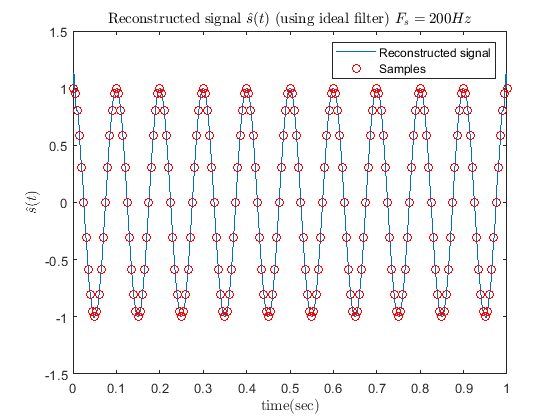

s_hat1_200 = Interpolate(se2,ne2,L2,FS2,1);
plot(t,s_hat1_200,n2/FS2,sd2,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using ideal filter) $F_s=200Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Interpolation (Mode 2):`

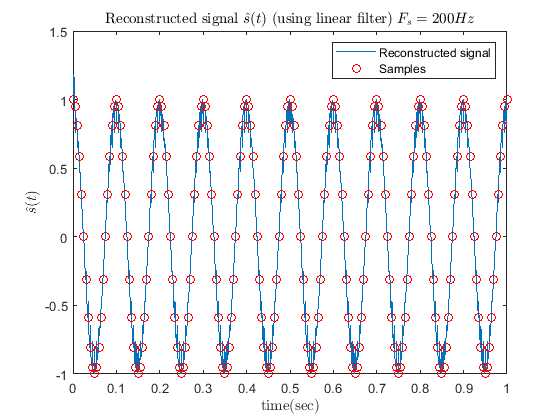

s_hat2_200 = Interpolate(se2,ne2,L2,FS2,2);
plot(t,s_hat2_200,n2/FS2,sd2,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using linear filter) $F_s=200Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Interpolation (Mode 3):`

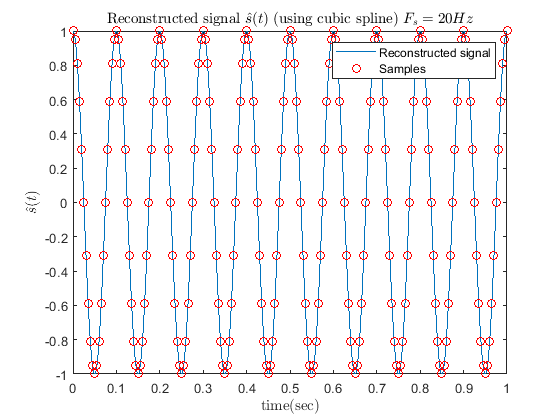

s_hat3_200 = Interpolate(se2,ne2,L2,FS2,3);
plot(t,s_hat3_200,n2/FS2,sd2,'ro');
title('Reconstructed signal $\hat{s}(t)$ (using cubic spline) $F_s=200Hz$','Interpreter','latex');
legend('Reconstructed signal','Samples');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{s}(t)$','Interpreter','latex');

`Mean Squared Error: `

% Fs = 20Hz

- ` mode = 1 (ideal filter)`

Er200_ideal = immse(s_hat1_200,s)

Er200_ideal = 1.6600e-04

        2. ` mode = 2 (linear filter)`

Er200_linear = immse(s_hat2_200,s)

Er200_linear = 0.0057

        3. ` mode = 3 (cubic spline)`

Er200_spline = immse(s_hat3_200,s)

Er200_spline = 5.0559e-10

# `Part 2:`

`Problem 1.`

clear;
[music,Fs1] = audioread('sound.mp3');
x = music(1:Fs1);
sound(x,Fs1);

`Problem 2.`

w = linspace(-pi,pi,length(x));
n = 0:(Fs1-1);
Xejw = DTFT(x,n,w);

 
$$\left|X\left(e^{j\omega } \right)\right|$$


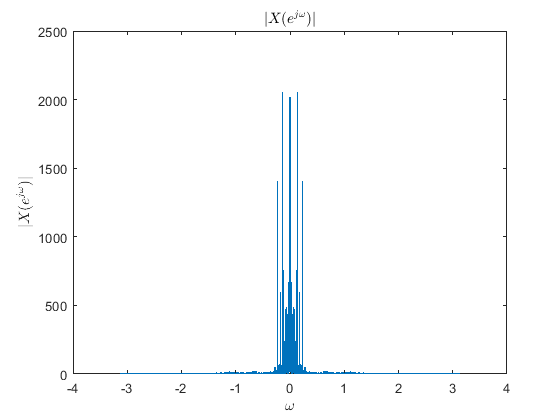

plot(w,abs(Xejw));
title('$|X(e^{j\omega})|$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|X(e^{j\omega})|$','Interpreter','latex');


$$\angle X\left(e^{j\omega } \right)$$


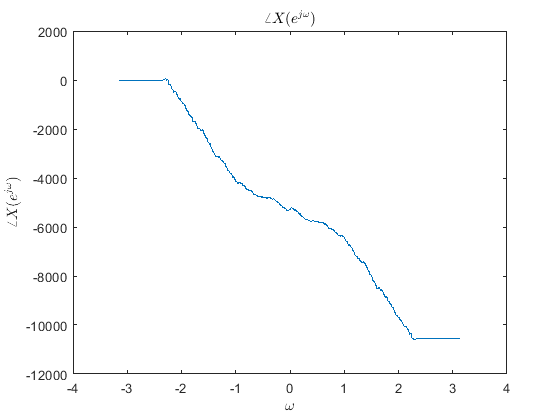

plot(w,phase(Xejw));
title('$\angle{X(e^{j\omega})}$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{X(e^{j\omega})}$','Interpreter','latex');

`Problem 4.`


$$L=3\;,M=2$$


`Expnader:`

L = 3;
[xe,ne] = Expander(x,n,L);
Fse = length(ne);

`Interpolator:`

ye = Interpolate(xe,ne,L,Fs1,3);

`Compressor:`

M = 2;
[xd,nd] = Compressor(ye,ne,M);
Fs2 = length(nd);

`Fourier transform of `$x\left\lbrack n\right\rbrack ,x_e \left\lbrack n\right\rbrack ,y_e \left\lbrack n\right\rbrack ,x_d \left\lbrack n\right\rbrack$`:`

XE_ejw = DTFT(xe,ne,w);
YE_ejw = DTFT(ye,ne,w);
XD_ejw = DTFT(xd,nd,w);

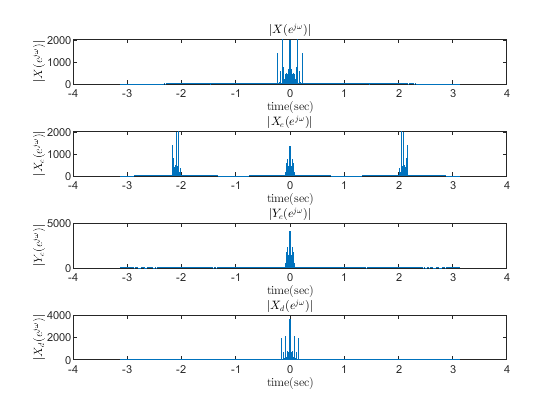

subplot(4,1,1);
plot(w,abs(Xejw));
title('$|X(e^{j\omega})|$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$|X(e^{j\omega})|$','Interpreter','latex');
subplot(4,1,2);
plot(w,abs(XE_ejw));
title('$|X_e(e^{j\omega})|$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$|X_e(e^{j\omega})|$','Interpreter','latex');
subplot(4,1,3);
plot(w,abs(YE_ejw));
title('$|Y_e(e^{j\omega})|$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$|Y_e(e^{j\omega})|$','Interpreter','latex');
subplot(4,1,4);
plot(w,abs(XD_ejw));
title('$|X_d(e^{j\omega})|$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$|X_d(e^{j\omega})|$','Interpreter','latex');

`Problem 5.D`

sound(xd,length(nd));
audiowrite('y_problem2.wav',xd,Fs2);

# `Part 3:`

    
$$x\left(t\right)=\left\lbrace \begin{array}{cc}
14 & ,0\le t\le 25\mu s\\
0 & ,25\mu s<t\le 2\ldotp 5\mathrm{ms}
\end{array}\right.$$


clear;
FsCT = 1000;
T = 2.5;
x(1:(25e-3*FsCT+1)) = 14;
x(T*FsCT) = 0;
w = -pi:1/10000:pi;

`Problem 1.`

`L = 0:`

L0 = 0;
n0 = 0:((L0+1)*T*FsCT-1); 
s0 = [];
for i = 0:L0
    s0 = [s0 x];
end
S0ejw = DTFT(s0,n0,w);

-  
$$\left|S\left(e^{j\omega } \right)\right|$$


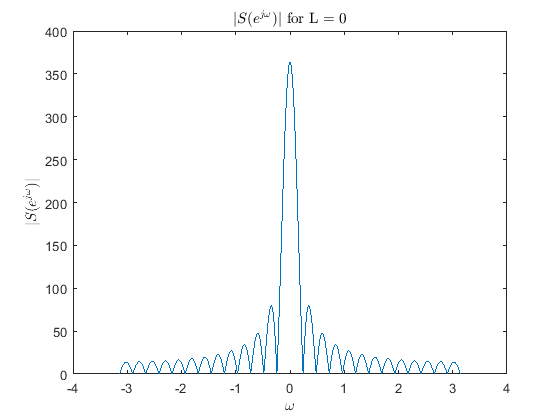

plot(w,abs(S0ejw));
title('$|S(e^{j\omega})|$ for L = 0','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle S\left(e^{j\omega } \right)$$


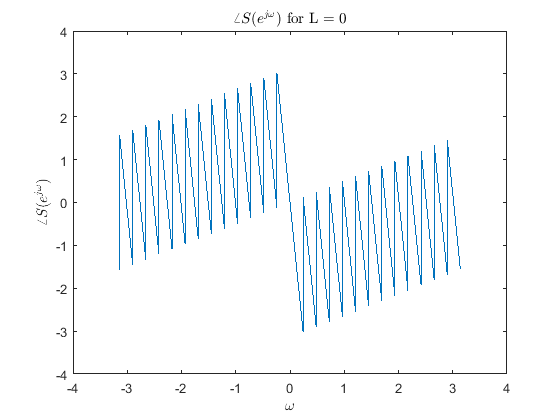

plot(w,phase(S0ejw));
title('$\angle{S(e^{j\omega})}$  for L = 0','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{S(e^{j\omega})}$','Interpreter','latex');

`Problem 2.`

ABS_S0 = abs(S0ejw);
Peak_S0 = max(ABS_S0);
i0 = min(find(ABS_S0 > Peak_S0/sqrt(2)));
j0 = max(find(ABS_S0 > Peak_S0/sqrt(2)));
BW_L0 = w(j0)-w(i0)

BW_L0 = 0.2142

BW_L0_per100 = BW_L0/(2*pi)

BW_L0_per100 = 0.0341

`Problem 3.`

`L = 2:`

L2 = 2;
n2 = 0:((L2+1)*T*FsCT-1); 
s2 = [];
for i = 0:L2
    s2 = [s2 x];
end
S2ejw = DTFT(s2,n2,w);

-  
$$\left|S\left(e^{j\omega } \right)\right|$$


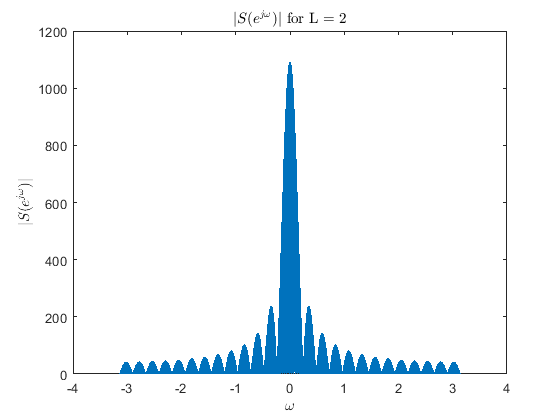

plot(w,abs(S2ejw));
title('$|S(e^{j\omega})|$ for L = 2','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle S\left(e^{j\omega } \right)$$


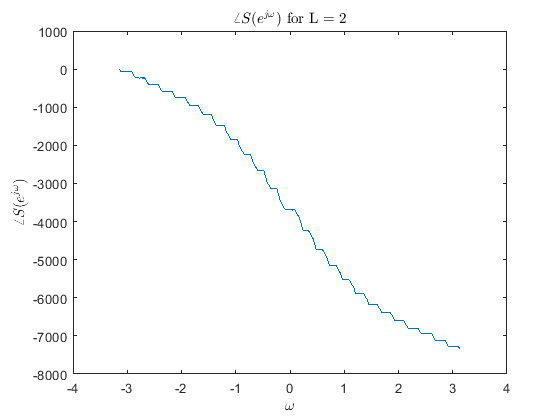

plot(w,phase(S2ejw));
title('$\angle{S(e^{j\omega})}$  for L = 2','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{S(e^{j\omega})}$','Interpreter','latex');

- `Bandwidth (3-dB):`

ABS_S2 = abs(S2ejw);
Peak_S2 = max(ABS_S2);
i2 = min(find(ABS_S2 > Peak_S2/sqrt(2)));
j2 = max(find(ABS_S2 > Peak_S2/sqrt(2)));
BW_L2 = w(j2)-w(i2)

BW_L2 = 0.2112

BW_L2_per100 = BW_L2/(2*pi)

BW_L2_per100 = 0.0336

`L = 5:`

L5 = 5;
n5 = 0:(L5+1)*T*FsCT-1; 
s5 = [];
for i = 0:L5
    s5 = [s5 x];
end
S5ejw = DTFT(s5,n5,w);

-  
$$\left|S\left(e^{j\omega } \right)\right|$$


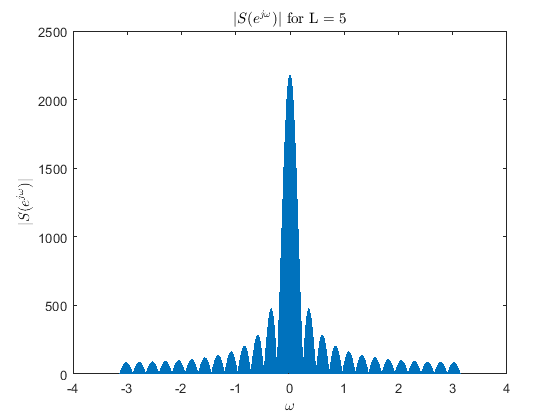

plot(w,abs(S5ejw));
title('$|S(e^{j\omega})|$ for L = 5','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle S\left(e^{j\omega } \right)$$


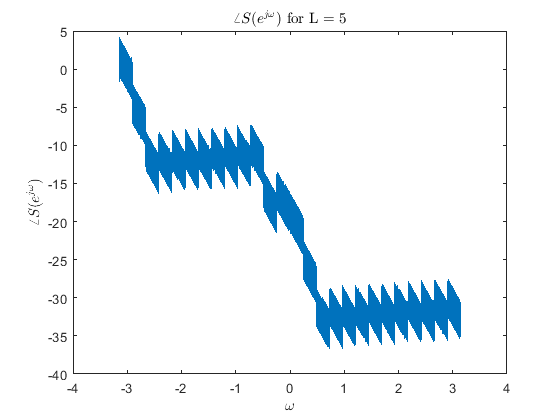

plot(w,phase(S5ejw));
title('$\angle{S(e^{j\omega})}$  for L = 5','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{S(e^{j\omega})}$','Interpreter','latex');

- `Bandwidth (3-dB):`

ABS_S5 = abs(S5ejw);
Peak_S5 = max(ABS_S5);
i5 = min(find(ABS_S5 > Peak_S5/sqrt(2)));
j5 = max(find(ABS_S5 > Peak_S5/sqrt(2)));
BW_L5 = w(j5)-w(i5)

BW_L5 = 0.2061

BW_L5_per100 = BW_L5/(2*pi)

BW_L5_per100 = 0.0328

`Problem 5.`

`L = 30`

L10 = 10;
n10 = 0:(L10+1)*T*FsCT-1; 
s10 = [];
for i = 0:L10
    s10 = [s10 x];
end
S10ejw = DTFT(s10,n10,w);

-  
$$\left|S\left(e^{j\omega } \right)\right|$$


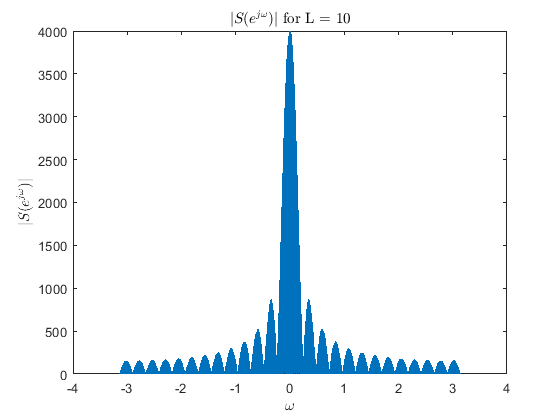

plot(w,abs(S10ejw));
title('$|S(e^{j\omega})|$ for L = 10','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle S\left(e^{j\omega } \right)$$


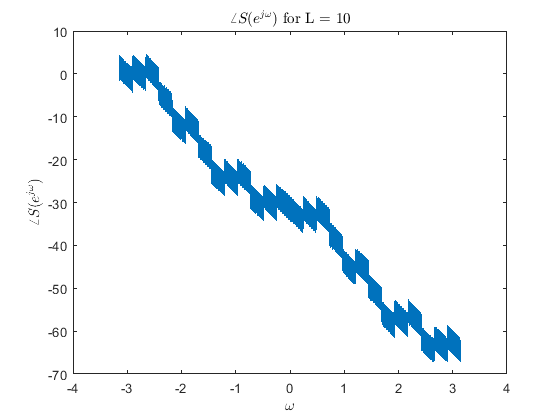

plot(w,phase(S10ejw));
title('$\angle{S(e^{j\omega})}$  for L = 10','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{S(e^{j\omega})}$','Interpreter','latex');

- `Bandwidth (3-dB):`

ABS_S10 = abs(S10ejw);
Peak_S10 = max(ABS_S10);
i10 = min(find(ABS_S10 > Peak_S10/sqrt(2)));
j10 = max(find(ABS_S10 > Peak_S10/sqrt(2)));
BW_L10 = w(j10)-w(i10)

BW_L10 = 0.1985

BW_L10_per100 = BW_L10/(2*pi)

BW_L10_per100 = 0.0316

# `Part 4:`

`Problem 1.`

  
$$s\left(t\right)=\cos \left(2\pi f_c t\right)\;,{\;f}_c =100\textrm{Hz}$$


clear;
FsCT = 10000;
w = -pi:1/10000:pi;
t = 0:1/FsCT:1;
fc = 100;
xc = cos(2*pi*fc*t);

    
$$\left|X_c \left(e^{j\omega } \right)\right|$$


Xcejw = DTFT(xc,t*FsCT,w);
plot(w*FsCT,abs(Xcejw)/length(xc));

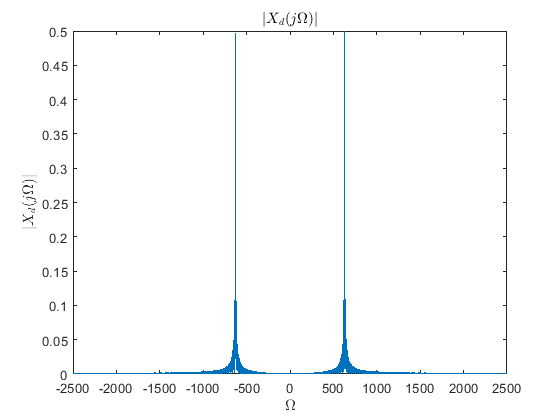

xlim([-2500 2500]);
title('$|X_d(j\Omega)|$','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|X_d(j\Omega)|$','Interpreter','latex');

`Problem 2.`

fs = 2*(2*fc);
xd = xc(1:FsCT/fs:length(xc));
n = 0:fs;

`Expander:`

L = 2;
[xe,ne] = Expander(xd,n,L);

`Interpolate:`

L = 2;
yc_ide = Interpolate(xe,ne,L,fs,1);
yc_lin = Interpolate(xe,ne,L,fs,2);
yc_spl = Interpolate(xe,ne,L,fs,3);
zc = filter([0.5 1 0.5],1,xe);
yc_fil = [0 zc(1:length(zc)-1)];

`DTFT:`

YCejw_ide = DTFT(yc_ide,ne,w);
YCejw_lin = DTFT(yc_lin,ne,w);
YCejw_spl = DTFT(yc_spl,ne,w);
YCejw_fil = DTFT(yc_fil,ne-1,w);

`Subplot:`

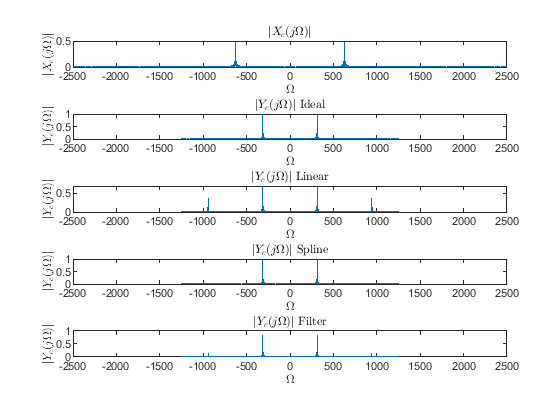

subplot(5,1,1);
plot(w*FsCT,abs(Xcejw)/length(xc));
xlim([-2500 2500]);
title('$|X_c(j\Omega)|$','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|X_c(j\Omega)|$','Interpreter','latex');

subplot(5,1,2);
plot(w*fs,abs(YCejw_ide)/fs);
xlim([-2500 2500]);
title('$|Y_c(j\Omega)|$ Ideal','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|Y_c(j\Omega)|$','Interpreter','latex');

subplot(5,1,3);
plot(w*fs,abs(YCejw_lin)/fs);
xlim([-2500 2500]);
title('$|Y_c(j\Omega)|$ Linear','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|Y_c(j\Omega)|$','Interpreter','latex');

subplot(5,1,4);
plot(w*fs,abs(YCejw_spl)/fs);
xlim([-2500 2500]);
title('$|Y_c(j\Omega)|$ Spline','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|Y_c(j\Omega)|$','Interpreter','latex');

subplot(5,1,5);
plot(w*fs,abs(YCejw_fil)/fs);
xlim([-2500 2500]);
title('$|Y_c(j\Omega)|$ Filter','Interpreter','latex');
xlabel('$\Omega$','Interpreter','latex');
ylabel('$|Y_c(j\Omega)|$','Interpreter','latex');

`Problem 3.`

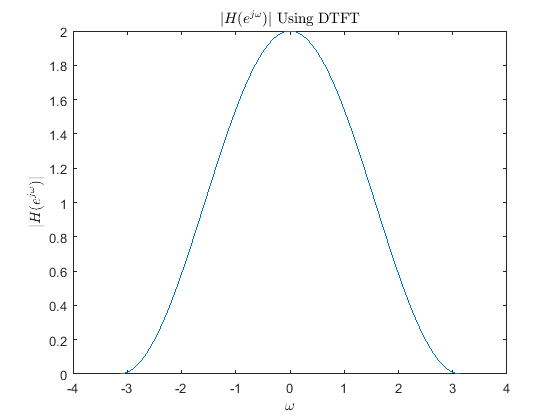

n12 = [-1 0 1];
h12 = [0.5 1 0.5];
HejwDTFT = DTFT(h12,n12,w); 
plot(w,abs(HejwDTFT));
title('$|H(e^{j\omega})|$ Using DTFT','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|H(e^{j\omega})|$','Interpreter','latex');

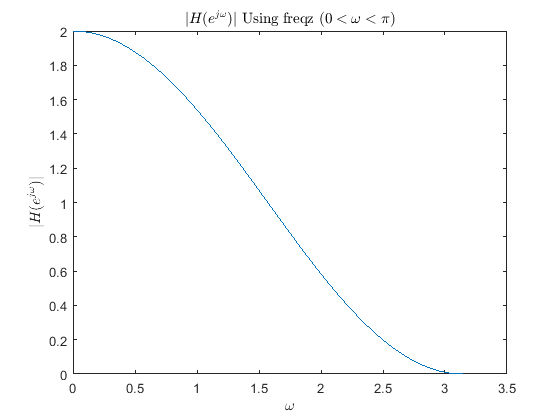

HejwFreqz = freqz([0.5 1 0.5],[0 1],length(w)/2);
plot(w(length(w)/2+1:length(w)),abs(HejwFreqz));
title('$|H(e^{j\omega})|$ Using freqz $(0<\omega<\pi)$','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|H(e^{j\omega})|$','Interpreter','latex');

`Problem 4.`

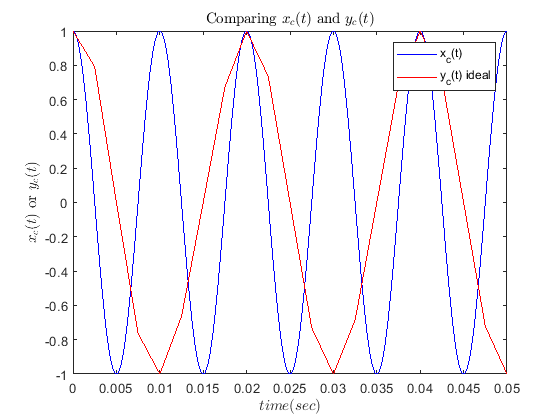

plot(t,xc,'b',ne/fs,yc_ide,'r');
xlim([0,0.05])
legend('x_c(t)','y_c(t) ideal');
title('Comparing $x_c(t)$ and $y_c(t)$','Interpreter','latex');
xlabel('$time(sec)$','Interpreter','latex');
ylabel('$x_c(t)$ or $y_c(t)$','Interpreter','latex');

# `Part 5:`

`Problem 1.`

- 
$$H\left(z\right)=\frac{1+2z^{-1} +3z^{-2} +4z^{-3} }{4+3z^{-1} +2z^{-2} +z^{-3} }$$


clear;
b = [1,2,3,4];
a = [4,3,2,1];
[H,w] = freqz(b,a,1000);

- 
$$|H\left(z\right)|$$


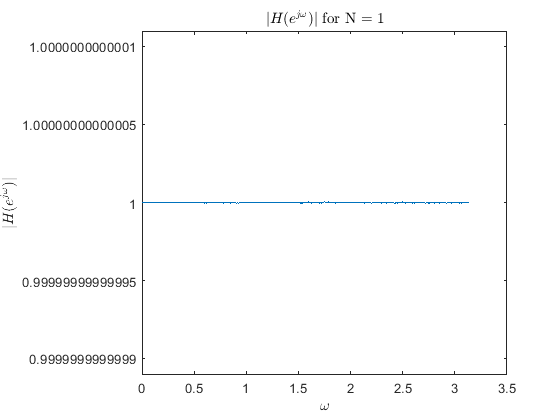

plot(w,abs(H));
title('$|H(e^{j\omega})|$ for N = 1','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|H(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle H\left(z\right)$$


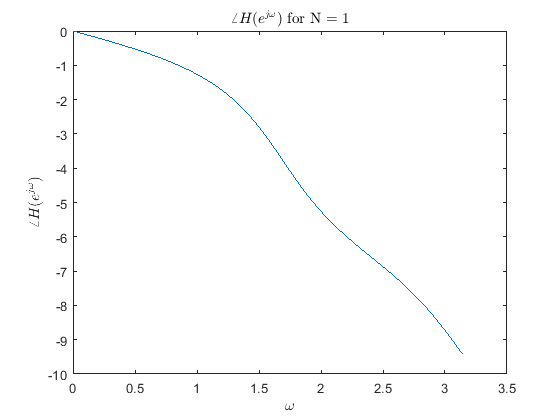

plot(w,phase(H));
title('$\angle{H(e^{j\omega})}$  for N = 1','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{H(e^{j\omega})}$','Interpreter','latex');

- `Poles and zeros:`

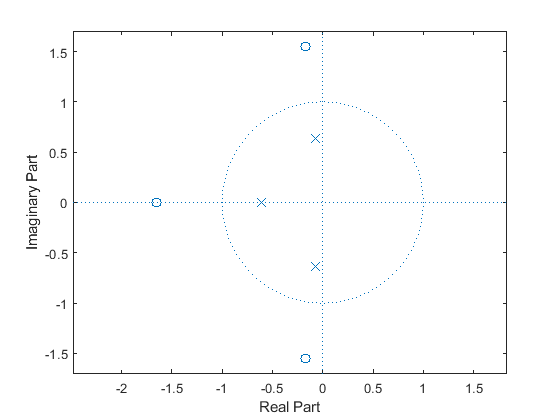

zplane(b,a);

`Problem 2.`

[speech,fs] = audioread('speech.wav');
output1 = filter(b,a,speech);
audiowrite('output1.wav',output1,fs);

`Problem 3.`

- 
$$H\left(z\right)={\left(\frac{1+2z^{-1} +3z^{-2} +4z^{-3} }{4+3z^{-1} +2z^{-2} +z^{-3} }\right)}^{15}$$


b15 = b;
a15 = a;
for i = 2:15
    b15 = conv(b15,b);
    a15 = conv(a15,a);
end
[H15,w] = freqz(b15,a15,1000);

- 
$$|H\left(z\right)|$$


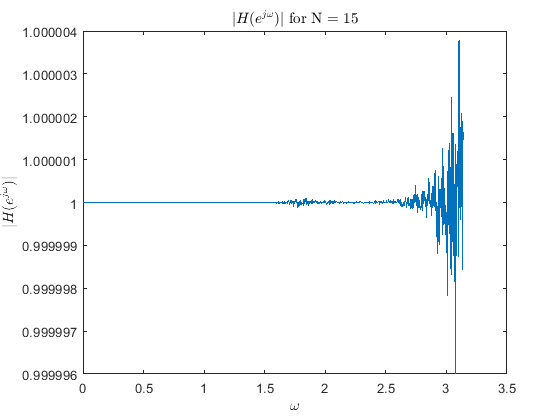

plot(w,abs(H15));
title('$|H(e^{j\omega})|$ for N = 15','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|H(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle H\left(z\right)$$


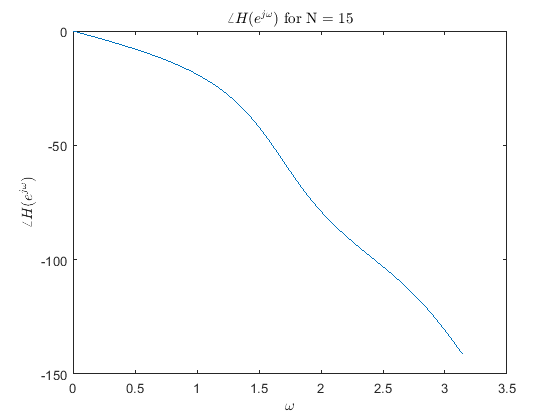

plot(w,phase(H15));
title('$\angle{H(e^{j\omega})}$  for N = 15','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{H(e^{j\omega})}$','Interpreter','latex');

- `Poles and zeros:`

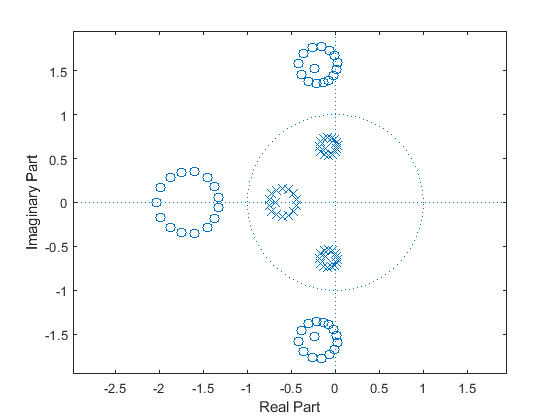

zplane(b15,a15);

`Problem 4.`

output2 = filter(b15,a15,speech);
audiowrite('output2.wav',output2,fs);

`Problem 5.`

- 
$$H\left(z\right)={\left(\frac{1+2z^{-1} +3z^{-2} +4z^{-3} }{4+3z^{-1} +2z^{-2} +z^{-3} }\right)}^{50}$$


b50 = b;
a50 = a;
for i = 2:50
    b50 = conv(b50,b);
    a50 = conv(a50,a);
end
[H50,w] = freqz(b50,a50,1000);

- 
$$|H\left(z\right)|$$


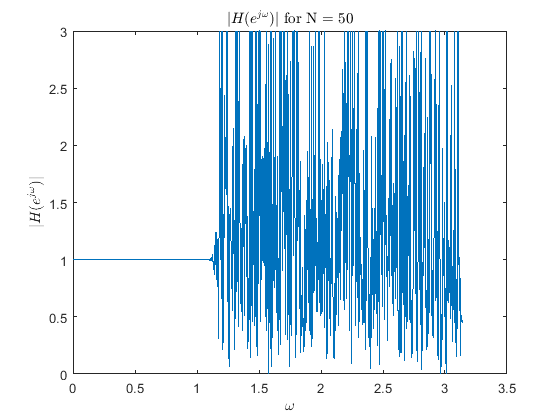

plot(w,abs(H50));
ylim([0,3]);
title('$|H(e^{j\omega})|$ for N = 50','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|H(e^{j\omega})|$','Interpreter','latex');

- 
$$\angle H\left(z\right)$$


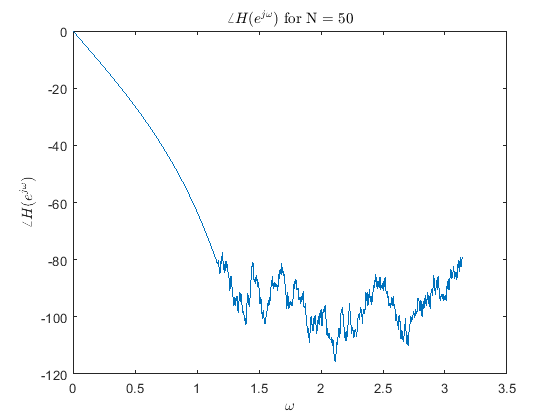

plot(w,phase(H50));
title('$\angle{H(e^{j\omega})}$  for N = 50','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$\angle{H(e^{j\omega})}$','Interpreter','latex');

- `Poles and zeros:`

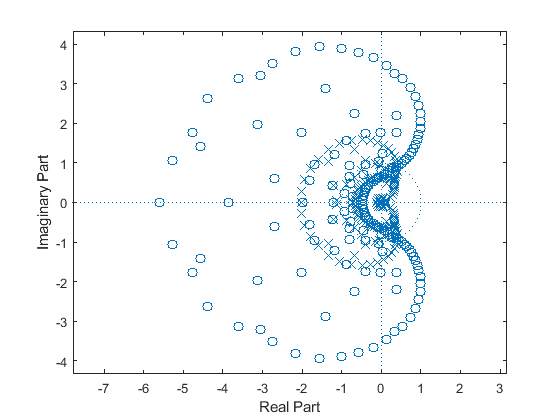

zplane(b50,a50);

- `Sound:`

output3 = filter(b50,a50,speech);
sound(output3,fs);

# `Part 6:`


$$y\left\lbrack n\right\rbrack -0\ldotp 4y\left\lbrack n-1\right\rbrack -0\ldotp 45y\left\lbrack n-2\right\rbrack =0\ldotp 45x\left\lbrack n\right\rbrack +0\ldotp 4x\left\lbrack n-1\right\rbrack -x\left\lbrack n-2\right\rbrack$$


clear;
n = 0:100;
a = [1 -0.4 -0.45];
b = [0.45 0.4 -1];
yi = [0 3];
xi = [2 2];
x = (1/2).^n + 2;
zi = filtic(b,a,yi,xi);

`Using residuez , conv and filtic:`

    
$$X^+ \left(z\right)=\frac{1}{1-\frac{1}{2}z^{-1} }+\frac{2}{1-z^1 }=\frac{3-2z^{-1} }{1-\frac{3}{2}z^{-1} +\frac{1}{2}z^{-2} }$$


ax = [1 -1.5 0.5];
bx = [3 -2];
ay = conv(a,ax);
by = conv(b,bx) + conv(zi,ax);
[r,p,c] = residuez(by,ay);
c


c =

     []



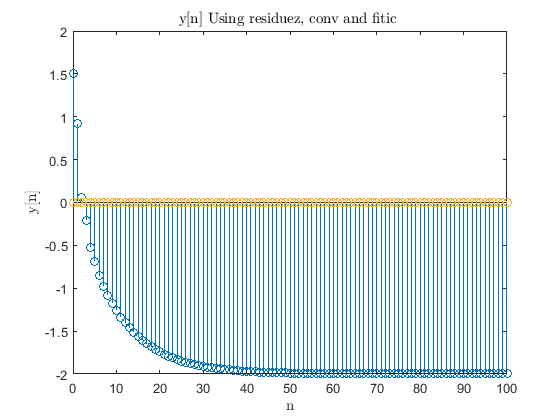

M = abs(p);
A = angle(p)/pi;
y1 = zeros(length(n));
for i = n
    y1(i+1) = sum(r.*exp(-1i*pi*i*A).*(M.^i));
end
stem(n,real(y1));
title('y[n] Using residuez, conv and fitic ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('y[n]','Interpreter','latex');

So:


$$Y^+ \left(z\right)=$$


`Using filtic and filter:`

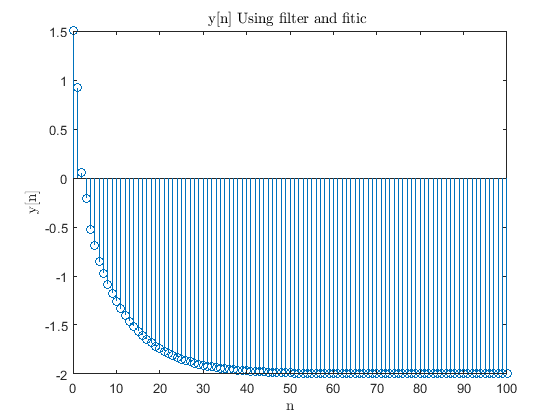

y2 = filter(b,a,x,zi);
stem(n,y2);
title('y[n] Using filter and fitic ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('y[n]','Interpreter','latex');

`According to Magnitude(M) and Angle(A) of 'p' and 'r':`

M'

ans =     1.0000    0.9000    0.5000    0.5000


A'

ans =      0     0     0     1


r'

ans =    -2.0000    2.1116    1.7188   -0.3304


`the complete response is:`


$$y\left\lbrack n\right\rbrack =-2u\left\lbrack n\right\rbrack +2\ldotp 1116{\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack +1\ldotp 7188{\left(0\ldotp 5\right)}^n u\left\lbrack n\right\rbrack -0\ldotp 3304{\left(-0\ldotp 5\right)}^n u\left\lbrack n\right\rbrack$$


`So the steady-state response is:`

 
$$y\left\lbrack n\right\rbrack =-2u\left\lbrack n\right\rbrack$$


`And the transient response is:`


$$y\left\lbrack n\right\rbrack =2\ldotp 1116{\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack +1\ldotp 7188{\left(0\ldotp 5\right)}^n u\left\lbrack n\right\rbrack -0\ldotp 3304{\left(0\ldotp 5\right)}^n e^{-j\pi n} u\left\lbrack n\right\rbrack$$


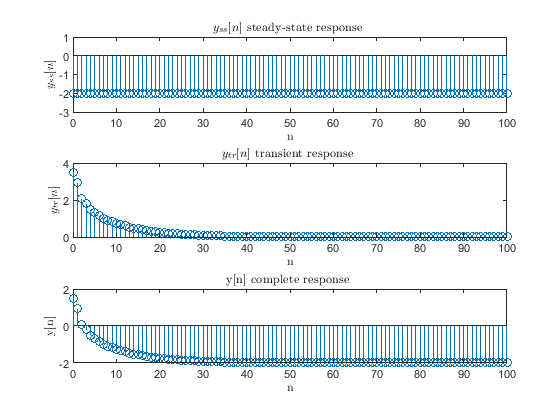

y = -2 + 2.1116*(0.9).^n + 1.7188*(0.5).^n - 0.3304*(-0.5).^n;
y_ss = -2*1.^n;
y_tr = 2.1116*(0.9).^n + 1.7188*(0.5).^n - 0.3304*(-0.5).^n;
subplot(3,1,1);
stem(n,y_ss);
ylim([-3 1]);
title('$y_{ss}[n]$ steady-state response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$y_{ss}[n]$','Interpreter','latex');
subplot(3,1,2);
stem(n,real(y_tr));
title('$y_{tr}[n]$ transient response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$y_{tr}[n]$','Interpreter','latex');
subplot(3,1,3);
stem(n,real(y));
title('y[n] complete response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('y[n]','Interpreter','latex');

`the zero-input response is:`

 
$$y_{\mathrm{zi}} \left\lbrack n\right\rbrack =2\ldotp 1116{\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack -0\ldotp 3304{\left(-0\ldotp 5\right)}^n u\left\lbrack n\right\rbrack$$


`And zero-state response is:`


$$y_{\mathrm{zc}} \left\lbrack n\right\rbrack =-2u\left\lbrack n\right\rbrack +1\ldotp 7188{\left(0\ldotp 5\right)}^n u\left\lbrack n\right\rbrack$$


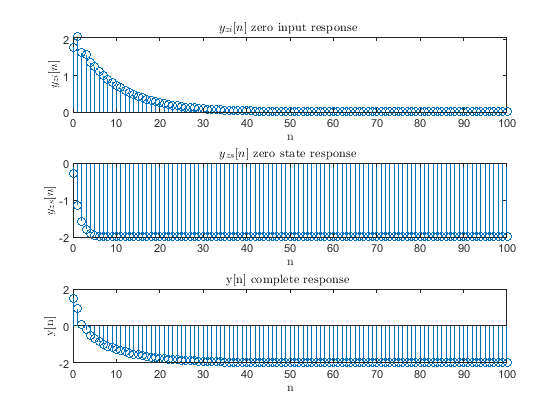

y_zi = 2.1116*(0.9).^n - 0.3304*(-0.5).^n;
y_zs = -2 + 1.7188*(0.5).^n;
subplot(3,1,1);
stem(n,real(y_zi));
title('$y_{zi}[n]$ zero input response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$y_{zi}[n]$','Interpreter','latex');
subplot(3,1,2);
stem(n,real(y_zs));
title('$y_{zs}[n]$ zero state response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('$y_{zs}[n]$','Interpreter','latex');
subplot(3,1,3);
stem(n,real(y));
title('y[n] complete response ','Interpreter','latex');
xlabel('n','Interpreter','latex');
ylabel('y[n]','Interpreter','latex');

# `Functions:`

`DTFT:`

function Xejw = DTFT (x,n,w)
    Xejw = zeros(1,length(w));
    for i = 1:length(w)
        Xejw(i) = sum(x.*exp(-1i*w(i)*n));
    end
end

function Xejw = DTFTfast (x,n,w)
    Xejw = x * exp(-1i*n'*w);
end

`Compressor:`

function [y,ny] = Compressor (x,nx,M)
    for j = 1:M
        if (mod(nx(j),M) == 0)
            i = j;
        end
    end
    y = x(i:M:length(x));
    ny = nx(i:M:length(nx))/M;
end

`Expander:`

function [y,ny] = Expander (x,nx,L)
    i = 1:L:(L*length(nx));
    y(i) = x;
    ny = (L*nx(1)):(L*nx(length(nx)));
end

`Interpolate:`

function [y] = Interpolate (x,n,L,fs,mode)
    n1 = n(1:L:length(n))/L;
    xc = x(1:L:length(x));
    t = n / (fs*L);
    if mode == 1
        y = xc * sinc(ones(length(n1),1)*n/L - n1'*ones(1,length(n)));
    elseif mode == 2
        x_lin = [zeros(1,L-1) x zeros(1,L-1)];
        n_lin = [-L+1:0 n length(n):length(n)+L-1];
        y = zeros(1,length(n));
        for i = n
            y(i+1) = sum(x_lin((i+1):(i+2*L-1)).*(1-abs(i-n_lin((i+1):(i+2*L-1)))/L));
        end
    elseif mode == 3
        y = spline(n1/fs,xc,t);
    else
        'invalid mode'
    end
end